# Breast cancer classification: held-out evaluation

This Live Script evaluates saved publication models through the current BANFF architecture. It reports the same task-level statistics and diagnostic plot families as the older task-specific implementation.

clearvars; close all; clc;

## Locate the publication code

evaluation_directory = fileparts(mfilename('fullpath'));
repository_root = fileparts(evaluation_directory);
addpath(repository_root, evaluation_directory);

## Choose the saved experiment family

Use the same profile and scientific overrides that were used for training.

seeds = 1:3;
profile = "main";            % main, full_rank, spsa, or neuron_sweep
overrides = struct();         % e.g. struct('N_hidden',8000) for neuron_sweep

## Choose display and export behaviour

display_options = struct();
display_options.representative_seed_index = 1;
display_options.representative_initial_condition = 1;
display_options.replay_static_spikes = true;
display_options.save_figures = false;
display_options.output_directory = fullfile(repository_root, ...
    'outputs', 'evaluation', 'breast_cancer');

## Run held-out testing, statistics, seed audit, and plots


BANFF held-out test evaluation: breast_cancer (main profile)
Seeds: [1 2 3]

Per-seed held-out test results
    Seed     Loss      AccuracyPercent    CrossEntropy    ActiveNeuronPercent
    ____    _______    _______________    ____________    ___________________

     1      0.12137        94.783           0.12137             99.891       
     2      0.11047        96.522           0.11047             97.366       
     3      0.11811        94.783           0.11811              98.25       

Across-seed mean and sample SD
           Metric             Mean      SampleSD     FiniteN
    _____________________    _______    _________    _______

    "Loss"                   0.11665   

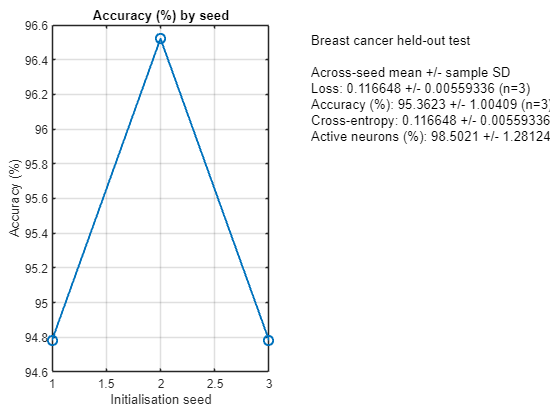

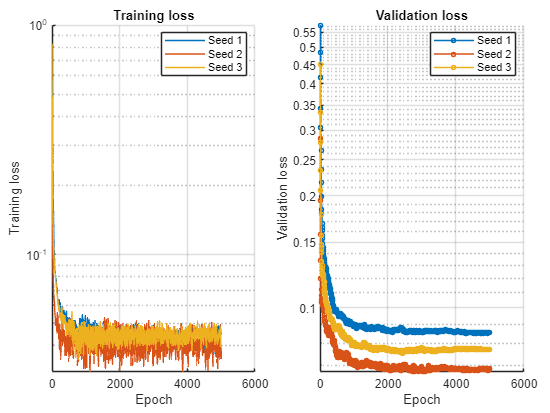

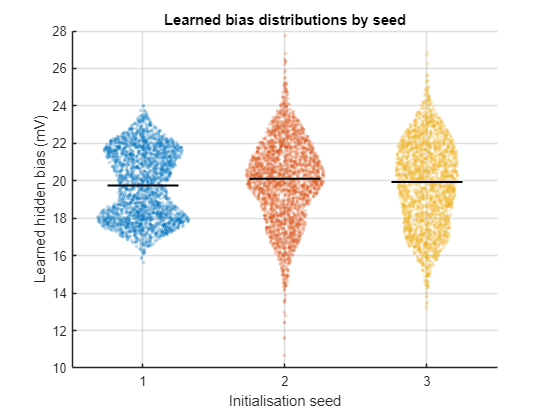

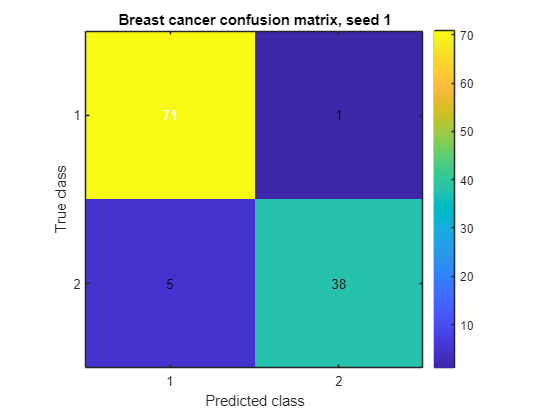

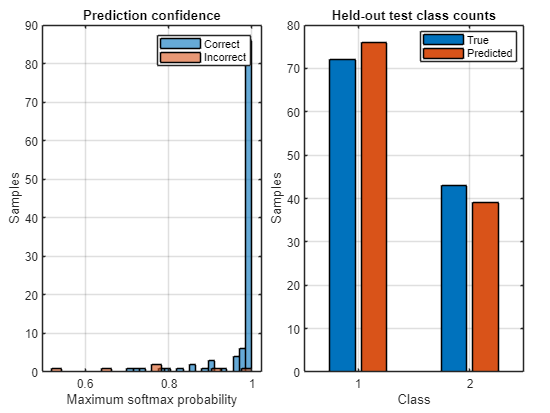

Exact full-held-out test current magnitudes (RMS over neurons, samples and time)
     Condition     EncoderRmsMv    NetRecurrentRmsMv    RecurrentToEncoderRms    GrossEncoderRmsMv    GrossRecurrentRmsMv    NetToGrossRecurrentRms    NetToGrossEncoderRms    AdaptationRmsMv    BiasDeviationRmsMv    DecoderContributionRms
    ___________    ____________    _________________    _____________________    _________________    ___________________    ______________________    ____________________    _______________    __________________    ______________________

    "Untrained"       2.0162            0.54168                0.2

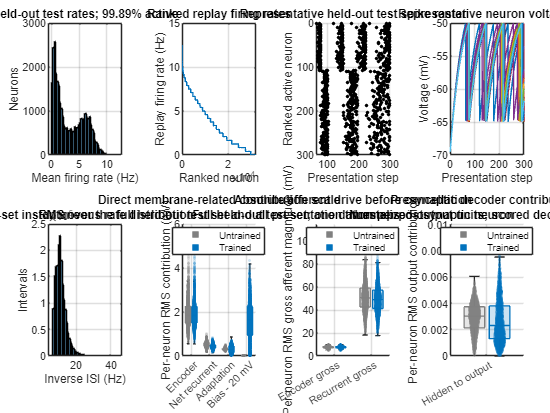

Current comparison: all 115 held-out test samples and 300 presentation steps (34500 observations per neuron and condition).


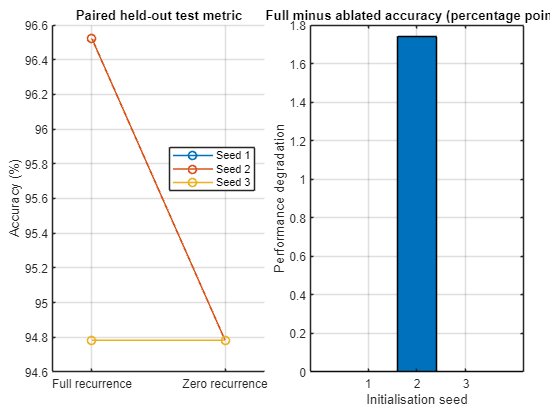

report = banff_evaluate_task("breast_cancer", seeds, profile, overrides, display_options);

## Machine-readable results

report.seed_table

ans = 3×5 table
    Seed     Loss      AccuracyPercent    CrossEntropy    ActiveNeuronPercent
    ____    _______    _______________    ____________    ___________________

     1      0.12137        94.783           0.12137             99.891       
     2      0.11047        96.522           0.11047             97.366       
     3      0.11811        94.783           0.11811              98.25       


report.summary_table

ans = 4×4 table
           Metric             Mean      SampleSD     FiniteN
    _____________________    _______    _________    _______

    "Loss"                   0.11665    0.0055934       3   
    "AccuracyPercent"         95.362       1.0041       3   
    "CrossEntropy"           0.11665    0.0055934       3   
    "ActiveNeuronPercent"     98.502       1.2812       3   


report.network_seed_audit

ans = 3×4 table
    Seed                                                                 ModelFile                                                                                           CheckpointHash                                                    FixedNetworkProbeHash                       
    ____    ___________________________________________________________________________________________________________________________________    __________________________________________________________________    __________________________________________________________________

     1      "/home/kai.mason/Documents/BANFF_SNN_pub/outputs/models/breast_cancer_eprop_low_rank_hard_spike_N32000_cfg016b3cad776a_seed001.mat"    "5c81b3133cc644102ef6f426650ec22fb098c66082cc7dba95385d902f4c58f4"    "8a03c9aaadeea75965e2aaf6a814128d01ed96aed177397bd05985505402d